**Latin HyperCube Sampling**

rng default % For reproducibility
lhsSampling = array2table(lhsdesign(2000,9));
lhsSampling.Properties.VariableNames = {'CoreInertia','CoreDamping','CombustorVolume',...
                                        'PTInertia','RotorInertia',...
                                        'PTNozzleOpening','PTDamping','RotorDamping','GearRatio'};

**Define Lower and Upper Bounds of the Design Variables**

designVar_CoreShaftInertia_lb = 0.05;
designVar_CoreShaftInertia_ub = 0.5;
designVar_CoreDampingCoeff_lb = 0.0005;
designVar_CoreDampingCoeff_ub = 0.005;
designVar_CombustorVolume_lb = 0.001;
designVar_CombustorVolume_ub = 0.01;
% designVar_FlowArea_lb = 0.005;
% designVar_FlowArea_ub = 0.5;
designVar_PTInertiaMultiplier_lb = 0.1;
designVar_PTInertiaMultiplier_ub = 0.8;
designVar_RotorInertiaMultiplier_lb = 0.1;
designVar_RotorInertiaMultiplier_ub = 0.8;
designVar_PTNozzleOpening_lb = 0.3;
designVar_PTNozzleOpening_ub = 1.0;
designVar_PTDampingCoeff_lb = 0.0005;
designVar_PTDampingCoeff_ub = 0.005;
designVar_RotorDampingCoeff_lb = 0.0005;
designVar_RotorDampingCoeff_ub = 0.005;
designVar_GearRatio_lb = 1.5;
designVar_GearRatio_ub = 6;

**Design Variable Table**

designVars = lhsSampling;
format short
designVars.CoreInertia = designVar_CoreShaftInertia_lb + lhsSampling.CoreInertia * (designVar_CoreShaftInertia_ub - designVar_CoreShaftInertia_lb);
designVars.CoreDamping = designVar_CoreDampingCoeff_lb + lhsSampling.CoreDamping * (designVar_CoreDampingCoeff_ub - designVar_CoreDampingCoeff_lb);
designVars.CombustorVolume = designVar_CombustorVolume_lb + lhsSampling.CombustorVolume * (designVar_CombustorVolume_ub - designVar_CombustorVolume_lb);
% designVars.FlowArea = designVar_FlowArea_lb + lhsSampling.FlowArea * (designVar_FlowArea_ub - designVar_FlowArea_lb);
designVars.PTInertia = designVars.CoreInertia .* (designVar_PTInertiaMultiplier_lb + lhsSampling.PTInertia * (designVar_PTInertiaMultiplier_ub - designVar_PTInertiaMultiplier_lb));
designVars.RotorInertia = designVars.CoreInertia .* (designVar_RotorInertiaMultiplier_lb + lhsSampling.RotorInertia * (designVar_RotorInertiaMultiplier_ub - designVar_RotorInertiaMultiplier_lb));
designVars.PTNozzleOpening = designVar_PTNozzleOpening_lb + lhsSampling.PTNozzleOpening * (designVar_PTNozzleOpening_ub - designVar_PTNozzleOpening_lb);
designVars.PTDamping = designVar_PTDampingCoeff_lb + lhsSampling.PTDamping * (designVar_PTDampingCoeff_ub - designVar_PTDampingCoeff_lb);
designVars.RotorDamping = designVar_RotorDampingCoeff_lb + lhsSampling.RotorDamping * (designVar_RotorDampingCoeff_ub - designVar_RotorDampingCoeff_lb);
designVars.GearRatio = designVar_GearRatio_lb + lhsSampling.GearRatio * (designVar_GearRatio_ub - designVar_GearRatio_lb);
summary(designVars)

Variables:
    CoreInertia: 2000×1 double
        Values:
            Min       0.05001 
            Median    0.27509 
            Max       0.49982 
    CoreDamping: 2000×1 double
        Values:
            Min       0.00050217
            Median     0.0027501
            Max        0.0049987
    CombustorVolume: 2000×1 double
        Values:
            Min        0.001001
            Median    0.0054997
            Max       0.0099994
    PTInertia: 2000×1 double
        Values:
            Min       0.0057988
            Median      0.10571
            Max         0.37768
    RotorInertia: 2000×1 double
        Values:
            Min       0.0071394
            Median      0.10475
            Max         0.39243
    PTNozzleOpening: 2000×1 double
        Values:
            Min       0.30006 
            Median    0.64997 
            Max       0.99987 
    PTDamping

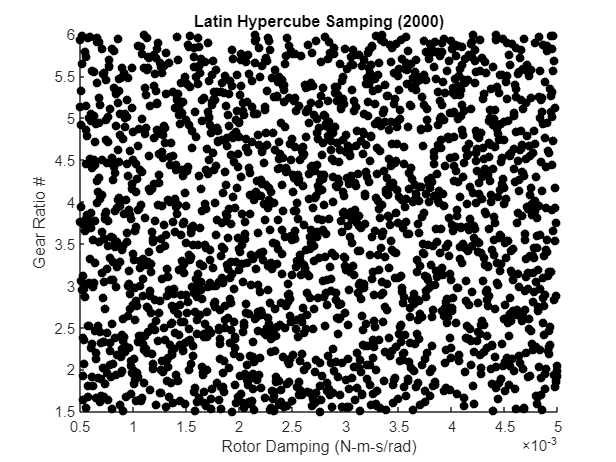

figure
scatter(designVars.RotorDamping,designVars.GearRatio,'k','filled')
xlabel('Rotor Damping (N-m-s/rad)')
ylabel('Gear Ratio #')
title('Latin Hypercube Samping (2000)')

**Speed & Surge Margin input**

t = (0:1:1200)';

Linear Ramp

% rpm = (0:10:12000)';

Ramp & Hold

rpm = (0:20:12000)';
rpm = [rpm; ones(height(t)-height(rpm),1)*12000];

% hold = ones(180,1);
% rpm = [hold; ones(20,1)*2000; hold*2000; ones(20,1)*4000; hold*4000; ones(20,1)*6000; hold*6000; ones(20,1)*8000; hold*8000; ones(20,1)*10000; hold*10000; ones(21,1)*12000;];

sm = ones(size(t))*0.2; %default 0.25
u = [rpm sm];

## Set Up Simulation

Set up the [`Simulink.SimulationInput`](https://www.mathworks.com/help/simulink/slref/simulink.simulationinput-class.html) object for each unique simulation.  Here we will set the variables that are changing for each iteration.  

**Note:** The loop is running backward to dynamically preallocate the data type.

for ii = height(designVars):-1:1
    simIn (ii) = Simulink.SimulationInput('TurboShaftEngine_mod');
    simIn (ii) = simIn (ii).setVariable('Core_Shaft_inertia',designVars.CoreInertia(ii));
    simIn (ii) = simIn (ii).setVariable('Core_Damping_Coeff',designVars.CoreDamping(ii));%designVars.CoreDamping(ii), default 0.001
    simIn (ii) = simIn (ii).setVariable('Combustor_volume',designVars.CombustorVolume(ii));
    simIn (ii) = simIn (ii).setVariable('Flow_area',0.01);%designVars.FlowArea(ii), default 0.01
    simIn (ii) = simIn (ii).setVariable('PT_Shaft_inertia',designVars.PTInertia(ii));
    simIn (ii) = simIn (ii).setVariable('PT_Nozzle_Opening',designVars.PTNozzleOpening(ii));
    simIn (ii) = simIn (ii).setVariable('PT_Damping_Coeff',designVars.PTDamping(ii));%designVars.PTDamping(ii), default 0.001
    simIn (ii) = simIn (ii).setVariable('Rotor_Damping_Coeff',designVars.RotorDamping(ii));%designVars.RotorDamping(ii), default 0.001
    simIn (ii) = simIn (ii).setVariable('GearRatio',designVars.GearRatio(ii));
    simIn (ii) = simIn (ii).setVariable('Rotor_Inertia',designVars.RotorInertia(ii));
end

try
    out = parsim(simIn , 'TransferBaseWorkspaceVariables', 'on', 'ShowProgress', true, 'UseFastRestart', false,'ShowSimulationManager','on')
catch ME
    fprintf('An error occurred during simulation: %s\n', ME.message);
end

[14-Feb-2024 20:41:23] Checking for availability of parallel pool...
[14-Feb-2024 20:41:23] Starting Simulink on parallel workers...
[14-Feb-2024 20:41:24] Configuring simulation cache folder on parallel workers...
[14-Feb-2024 20:41:24] Transferring base workspace variables used in the model to parallel workers...
[14-Feb-2024 20:41:40] Loading model on parallel workers...
[14-Feb-2024 20:42:01] Running simulations...


[14-Feb-2024 23:26:56] Cleaning up parallel workers...


out = 1x2000 Simulink.SimulationOutput array



save lhs2000.mat out simIn

Error using save
Unable to save file 'C:\Users\ppankaj\OneDrive - MathWorks\My_Projects\ROM_AeroEngine\lhs2000.mat'. The file could not be closed, and might now be corrupt.

**Test Run**

simIn (1) = Simulink.SimulationInput('TurboShaftEngine_mod');
simIn (1) = simIn (1).setVariable('Core_Shaft_inertia',0.1);
simIn (1) = simIn (1).setVariable('Core_Damping_Coeff',0.001);
simIn (1) = simIn (1).setVariable('Combustor_volume',0.01);
simIn (1) = simIn (1).setVariable('Flow_area',0.01);
simIn (1) = simIn (1).setVariable('PT_Shaft_inertia',0.1/3);
simIn (1) = simIn (1).setVariable('PT_Nozzle_Opening',0.5);
simIn (1) = simIn (1).setVariable('PT_Damping_Coeff',0.001);
simIn (1) = simIn (1).setVariable('GearRatio',6);
simIn (1) = simIn (1).setVariable('Rotor_Inertia',0.02);
simIn (1) = simIn (1).setExternalInput([t u]);
outTest = parsim(simIn(1))

[13-Feb-2024 00:42:48] Checking for availability of parallel pool...
[13-Feb-2024 00:42:49] Starting Simulink on parallel workers...
[13-Feb-2024 00:42:49] Configuring simulation cache folder on parallel workers...
[13-Feb-2024 00:42:49] Loading model on parallel workers...
[13-Feb-2024 00:42:51] Running simulations...
[13-Feb-2024 00:43:09] Completed 1 of 1 simulation runs
[13-Feb-2024 00:43:09] Cleaning up parallel workers...


outTest =   Simulink.SimulationOutput:

                     logsout: [1x1 Simulink.SimulationData.Dataset] 
     simlog_TurboShaftEngine: [1x1 simscape.logging.Node] 
                        tout: [247x1 double] 

          SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
                ErrorMessage: [0x0 char] 


% Core_Shaft_inertia = 0.1; %default 0.1
% Core_Damping_Coeff = 0.001; %default 0.001
% Combustor_volume = 0.01; %default 0.001
% Flow_area = 0.01; %default 0.01
% PT_Shaft_inertia = Core_Shaft_inertia/3; %default I/5
% PT_Nozzle_Opening = 0.5; %default 0.5
% PT_Damping_Coeff = 0.001; %default 0.001
% GearRatio = 6; %default 6.0
% Rotor_Inertia = Core_Shaft_inertia/5; %default I/10

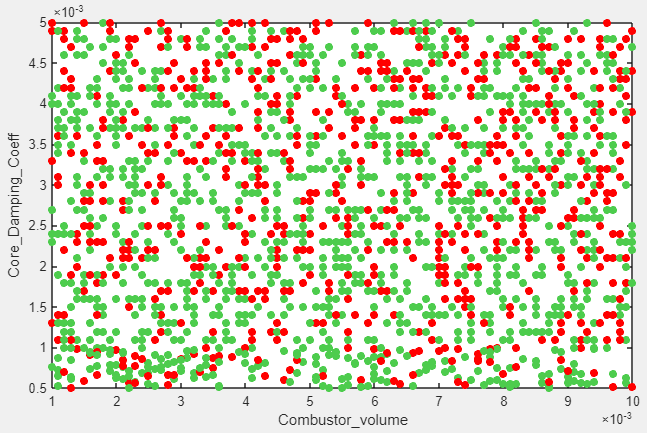

1262 successful runs out of 2000

**Log Simulation Results into Data Table**

j=1;
for i=1:height(out')
    if isempty(out(1,i).ErrorMessage)
        Time = timeseries2timetable(out(1,i).logsout{1}.Values).Time;
        heatInput = timeseries2timetable(out(1,i).logsout{1}.Values);
        nozzleOpening = timeseries2timetable(out(1,i).logsout{2}.Values);
        power = timeseries2timetable(out(1,i).logsout{3}.Values);
        efficiency = timeseries2timetable(out(1,i).logsout{4}.Values);
        % Simscape Results
        fullResults = out(1, i).simlog_TurboShaftEngine.TurboShaftEngine;
        
        CoreTurbine_FluidPower = values(fullResults.CoreTurbine.fluid_power.series);
        Compressor_FluidPower = values(fullResults.Compressor.fluid_power.series);
        CorePower = (CoreTurbine_FluidPower - Compressor_FluidPower)*1000; % in Watts or N-m/sec
        TurbineOutletVelocity = abs(values(fullResults.CoreTurbine.outlet_velocity.series)); % in m/sec
        Thrust_Core = CorePower ./ TurbineOutletVelocity;

        PT_FluidPower = values(fullResults.PowerTurbine.fluid_power.series)*1000; % in Watts or N-m/sec
        PTOutletVelocity = abs(values(fullResults.PowerTurbine.outlet_velocity.series)); % in m/sec
        Thrust_PT = PT_FluidPower ./ PTOutletVelocity;

        Thrust_Net = Thrust_Core+Thrust_PT;
        Thrust_Net = table(Time, Thrust_Net);
        Thrust_Net = table2timetable(Thrust_Net);

        Thrust_PT = table2timetable(table(Time, Thrust_PT));
        Thrust_Core = table2timetable(table(Time, Thrust_Core));


        simOut(j,1:8) = table(i,{heatInput},{nozzleOpening},{power},{efficiency},...
                              {Thrust_Core},{Thrust_PT},{Thrust_Net});

        j=j+1;
    end
end
simOut.Properties.VariableNames = {'RunID','HeatInput_kW','TurbineNozzleOpening','ShaftPower_kW','ShaftMechEfficiency','Thrust','ThrustPT','ThrustNet_N'};
designVariables = designVars(simOut.RunID,:); % Only retain succesful execution from the DOE

save DOE_LHS2000 designVariables simOut t u rpm sm

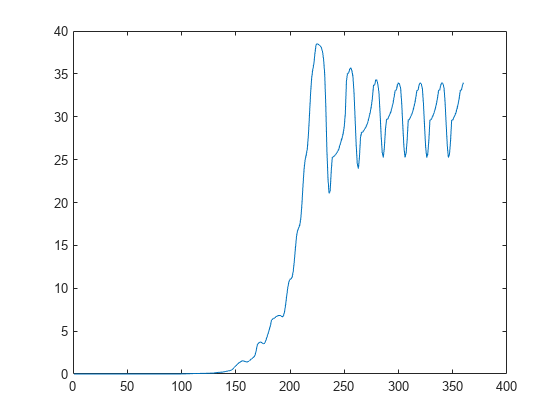

simscape_data = values(simlog_TurboShaftEngine.TurboShaftEngine.PowerTurbine.fluid_power.series);
% Access the Simscape logging data
% simscape_data = simlog_TurboShaftEngine.get('TurboShaftEngine/Compressor/fluid_power');
% assignin('base', 'exported_data', simscape_data);
plot(simscape_data)

openSimulationManager(simIn, out)

Open Results from a **specific RunID**

runID = 1950;
Time = timeseries2timetable(out(1,runID).logsout{1}.Values).Time;
fullResults = out(1, runID).simlog_TurboShaftEngine.TurboShaftEngine;

PT_FluidPower = values(fullResults.PowerTurbine.fluid_power.series);
CoreTurbine_FluidPower = values(fullResults.CoreTurbine.fluid_power.series);
Compressor_FluidPower = values(fullResults.Compressor.fluid_power.series);

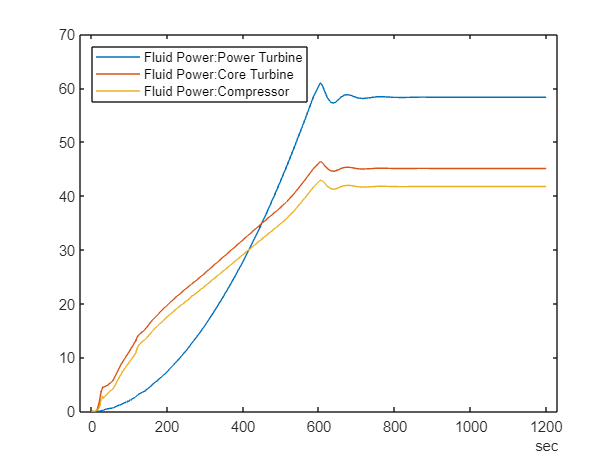

figure
plot(Time,PT_FluidPower)
hold on
plot(Time,CoreTurbine_FluidPower)
plot(Time,Compressor_FluidPower)
legend('Fluid Power:Power Turbine','Fluid Power:Core Turbine','Fluid Power:Compressor','Location','northwest')

CorePower = (CoreTurbine_FluidPower - Compressor_FluidPower)*1000; % in Watts or N-m/sec
TurbineOutletVelocity = abs(values(fullResults.CoreTurbine.outlet_velocity.series)); % in m/sec
Thrust_Core = CorePower ./ TurbineOutletVelocity;
PTOutletVelocity = abs(values(fullResults.PowerTurbine.outlet_velocity.series)); % in m/sec
Thrust_PT = PT_FluidPower*1000 ./ PTOutletVelocity;
NetThrust = Thrust_Core+Thrust_PT;

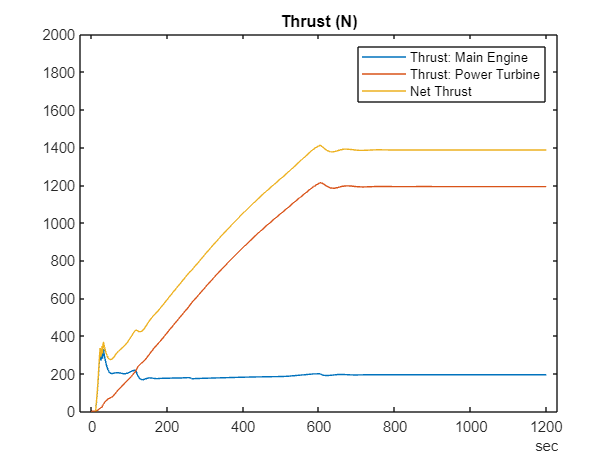

figure
plot(Time,Thrust_Core)
hold on
plot(Time,Thrust_PT)
plot(Time,NetThrust)
title('Thrust (N)')
ylim([0 2000])
legend('Thrust: Main Engine','Thrust: Power Turbine','Net Thrust')